## Bisection - Newton method

clear all;
close all;
clc;

The idea is to employing the bisection method to predict the initial guess $x^{(0)}$ for then apply the bisection method

f = @(x) atan(7 * (x - pi/2)) + sin((x - pi/2).^3);

#### a. Plot the function in interval [-1, 6]

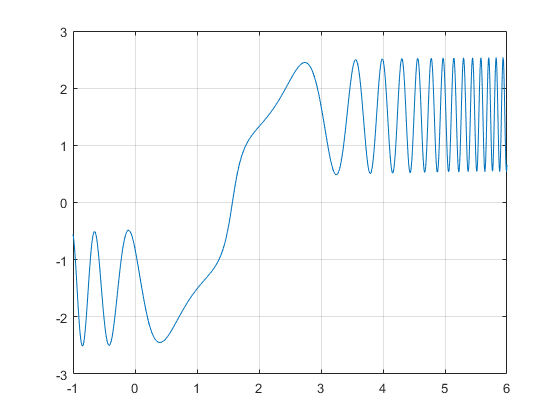

x = linspace(-1, 6, 1000);

figure();
plot(x, f(x));
grid on;

#### b. Newton method with $x^{(0)} = 1.5$

tol = 10e-10;
x0 = 1.5;
Nmax = 1000;

df = @(x) 7 ./ ( 1 + 49 * ( x-pi/2 ).^2 ) + 3 * (x-pi/2).^2 .* cos( (x-pi/2).^3 );

[x, x_iter] = newton(f, df, x0, tol, Nmax);

fprintf('x: %g\n', x);

x: 1.5708


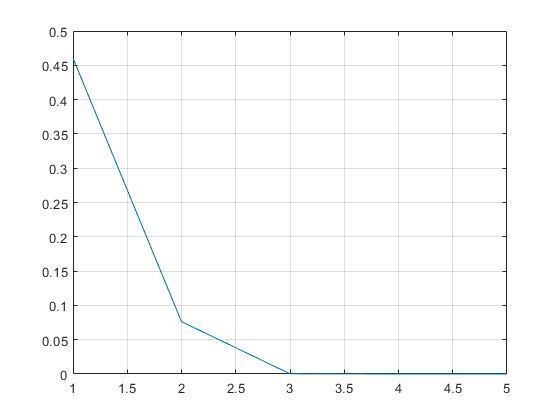

x_iter;

error = abs(f(x_iter));

figure();
plot(error);
grid on;

#### c. Netwon method with $x^{(0)} = 4$

x0 = 4;

[x, x_iter] = newton(f, df, x0, tol, Nmax);

fprintf('x: %g\n', x);

x: 23.9542


x_iter

x_iter =     4.0000    4.7221    4.6746    4.3544    4.4455    4.3325    4.5017    4.4409    4.1792    4.1117    4.1705    4.0751    4.1558    9.7380    9.7485    9.7393    9.8281    9.8339    9.8234    9.8329    9.7911    9.8036    9.7954    9.8019    9.7317    9.7394    9.9183    9.9242    9.9047    9.8896    9.8953    9.8873    9.8937    9.8359    9.8299    9.8364    9.8306    9.8387    9.8323    9.8843    9.8939    9.8637    9.8411    9.8325   10.1084   10.0997   10.1562   10.1686   10.1499   10.1571


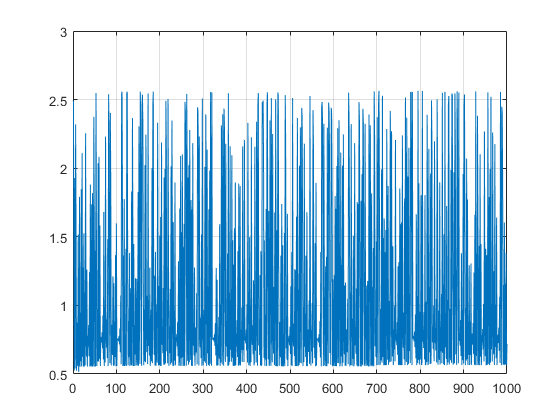


error = abs(f(x_iter));

figure();
plot(error);
grid on;

#### d. Bisection method in the interval [-1, 6]

a = -1;
b = 6;
tol = (b-a)/2^30;

[x, x_iter] = bisection(f, a, b, tol);

fprintf('x: %g\n', x);

x: 1.5708


x_iter

x_iter =     2.5000    0.7500    1.6250    1.1875    1.4063    1.5156    1.5703    1.5977    1.5840    1.5771    1.5737    1.5720    1.5712    1.5707    1.5710    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708


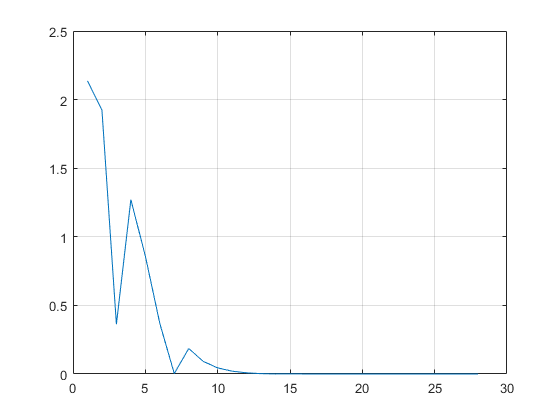


error = abs(f(x_iter));

figure();
plot(error);
grid on;

### Functions

#### Bisection method

function [x, x_iter] = bisection(f, a, b, tol, x_iter)
    Nmax = ceil(log((b-a/tol))/log(2));
    
    for i = 1:Nmax
        x_iter(i) = (b+a)/2;
        
        if f(x_iter(i))*f(a) < 0
            b = x_iter(i);
        else
            a = x_iter(i);
        end
    end
    
    x = x_iter(end);
end

#### Newton method

function [x, x_iter] = newton(f, df, x0, tol, Nmax)
    % Nmax since we don't know a priori if with the passed
    % tol we will reach a convergence

    x_iter(1) = x0;
    
    for k = 2:Nmax
        
        % Check if the derivative is zero or simil-zero
        if abs(df(x_iter(k-1))) < 1e-8
            break;
        end
        
        x_iter(k) = x_iter(k-1) - (f(x_iter(k-1)) / df(x_iter(k-1)));
    
        if abs(x_iter(k) - x_iter(k-1)) < tol
            break;
        end
    end
    
    x = x_iter(end);
end